RTS Smoother.

clear
load a1Sparse.mat
Q = diag(Q);
R = diag(R);

P_prev = [];
x_prev = [];
K = [];
P_post = [];
x_post = [];
x_final = [];
P_final = [];
V = v*0.1;
Q= (0.1^2)*Q;

%Forward Pass
delta_flyer = 1000;
for i = 1:sizet(1,1)
    
    if i ==1
        
        P_prev(i,1) = Q(1,1);
        x_prev(i,1) = 0;
        K(i,1) = P_prev(i,1)*(P_prev(i,1)+R(i,1))^-1;
        P_post(i,1) = P_prev(i,1);
        %P_post(i,1) = (1-K(i,1))*P_prev(i,1);
        x_post(i,1) = x_prev(i,1);
        %x_post(i,1) = x_prev(i,1)+K(i,1)*(yk_meas(i,1)-x_prev(i,1));
        
    elseif mod(i,delta_flyer)==0
        
        P_prev(i,1) = P_post(i-1,1) + Q(i,1);
        x_prev(i,1) = x_post(i-1) + V(i,1);
        K(i,1) = P_prev(i,1)*(P_prev(i,1)+R(i,1))^-1;
        P_post(i,1) = (1-K(i,1))*P_prev(i,1);
        x_post(i,1) = x_prev(i,1)+K(i,1)*(yk_meas(i,1)-x_prev(i,1));  
      
    else 
        
        P_prev(i,1) = P_post(i-1,1) + Q(i,1);
        x_prev(i,1) = x_post(i-1) + V(i,1);
        K(i,1) = P_prev(i,1)*(P_prev(i,1)+R(i,1))^-1;
        P_post(i,1) = P_prev(i,1);
        %P_post(i,1) = (1-K(i,1))*P_prev(i,1);
        x_post(i,1) = x_prev(i,1);
        %x_post(i,1) = x_prev(i,1)+K(i,1)*(yk_meas(i,1)-x_prev(i,1));
                
    end    
end

%Backward Pass
x_final(sizet(1,1),1) = x_post(sizet(1,1),1);
P_final(sizet(1,1),1) = P_post(sizet(1,1),1);
for i = sizet(1,1):-1:2
    
    P_final(i-1,1) = P_post(i-1,1)+(P_post(i-1,1)*((P_prev(i,1))^-1))*(P_final(i,1)-P_prev(i,1))*((P_post(i-1,1)*((P_prev(i,1))^-1).'));
    x_final(i-1,1) = x_post(i-1,1)+(P_post(i-1,1)*((P_prev(i-1,1))^-1))*(x_final(i,1)-x_prev(i,1));
    
    
    
end

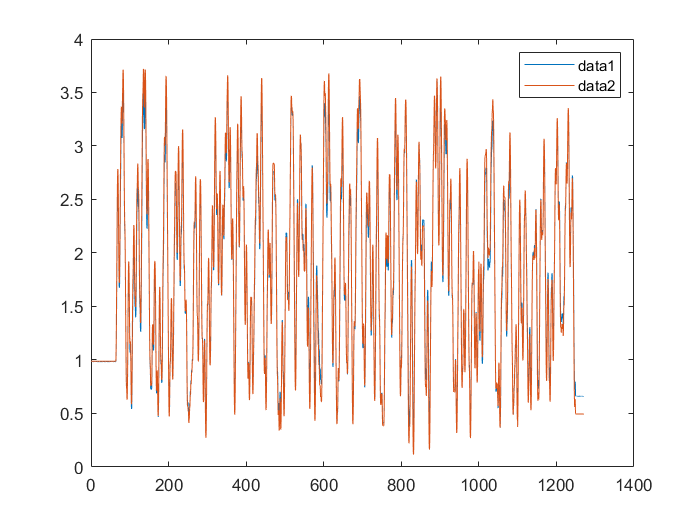

figure
plot(t,x_true)
hold on
plot(t,x_final)
legend

xf = x_final-x_true;
std_dev = sqrt(P_final);

For error plots:

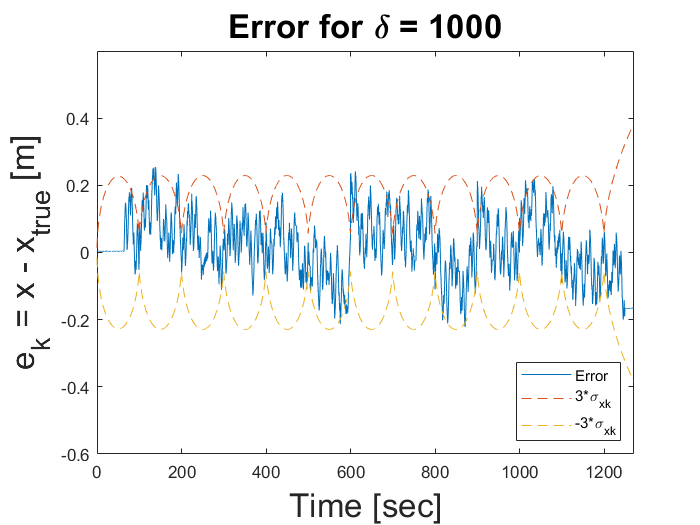

figure
plot(t,xf,t,3*std_dev,'--',t,-3*std_dev,'--')
legend('Error','3*\sigma_{xk}','-3*\sigma_{xk}', 'Location','southeast')
xlim([0,1271])
%xlim([0,50])
ylim([-0.6,0.6])
title(['Error for \delta = ' ,num2str(delta_flyer)],'FontSize',20)
xlabel('Time [sec]','FontSize',20)
ylabel('e_{k} = x - x_{true} [m]','FontSize',20)

%figure
%ploterrhist(xf,'bins',30)

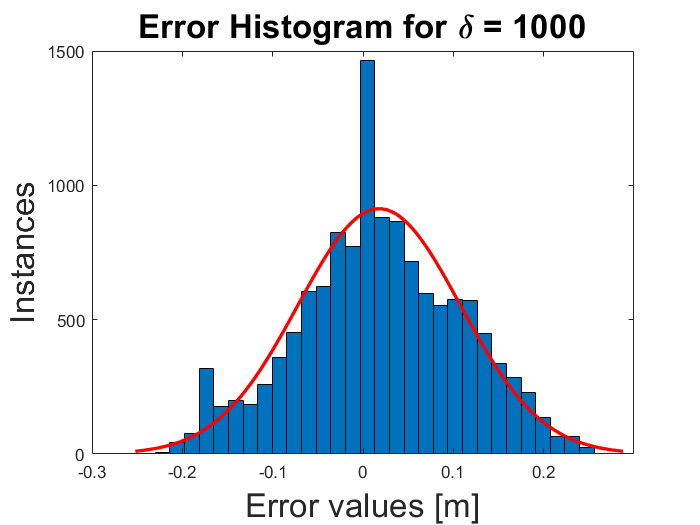

figure
histfit(xf,30)
xlim([-0.3,0.3])
xlabel('Error values [m]','FontSize',20)
ylabel('Instances','FontSize',20)
title(['Error Histogram for \delta = ',num2str(delta_flyer)],'FontSize',20)